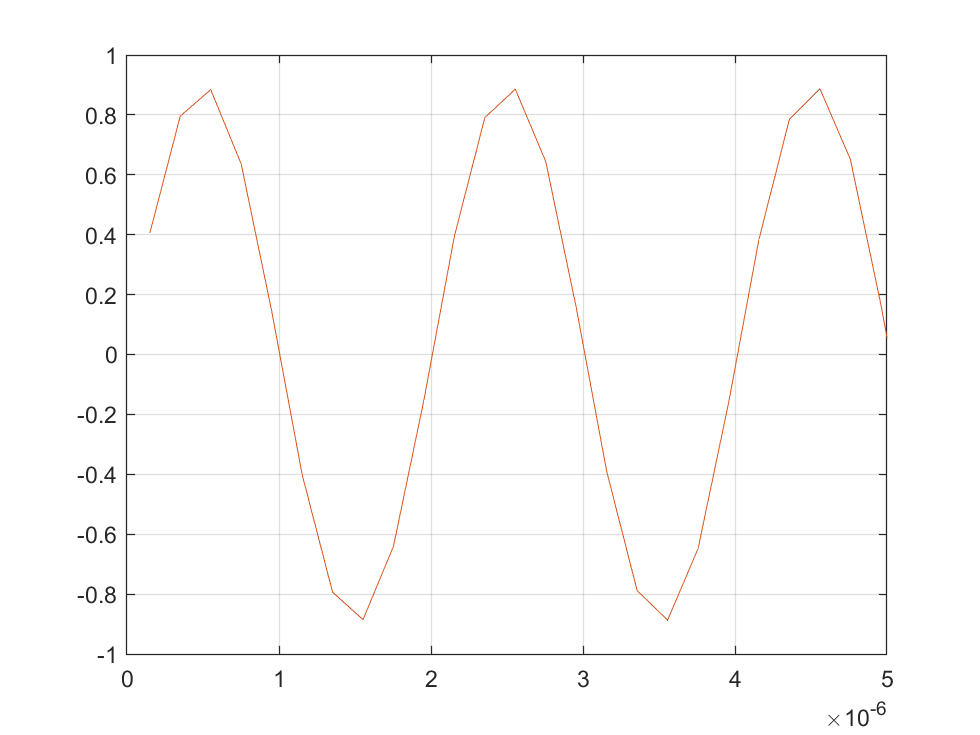

clc
clear
Fs = 5E6;
Fin = 51/512*Fs;
win = Fin * 2 * pi;
V0 = 0.895;
timeoffset = 150e-9;
t = linspace(timeoffset,51/Fin + timeoffset,512);
V_mag = [-0.966, -83.52, -80.417];
Sine = [sin(win.*t); sin(2*win.*t); sin(3*win.*t)];
Vout = db2mag(V_mag) * Sine;
Vin = V0*Sine(1,:);

Vds = Vout - Vin;

figure()
plot(t, [Vout; Vin]);
grid on;
xlim([0, 5e-6])

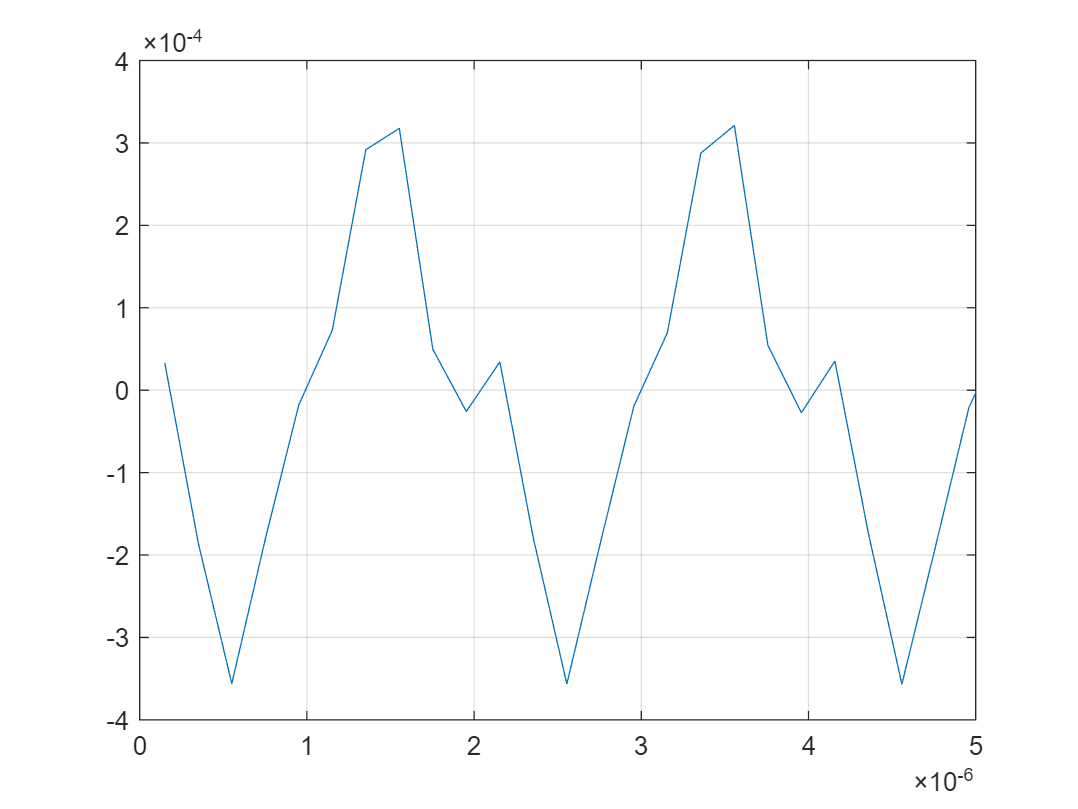


figure()
plot(t, Vds);
grid on;
xlim([0, 5e-6])

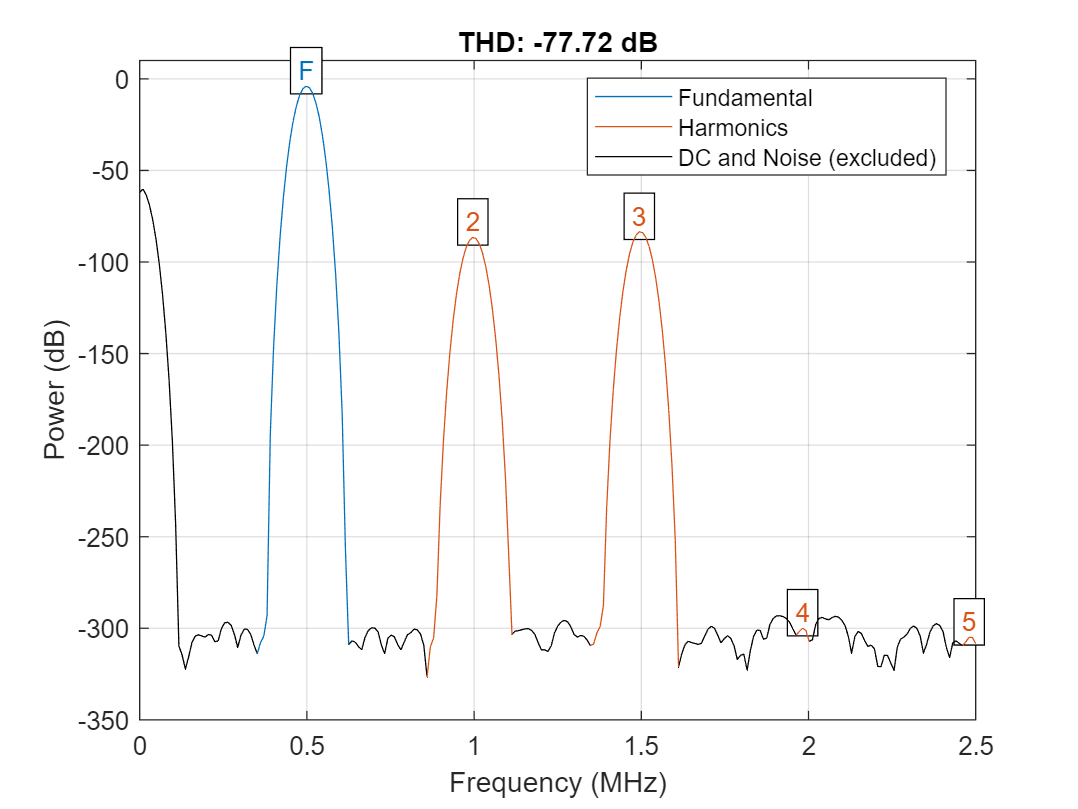

ans = -77.7208



figure()
thd(Vout, Fs)


[r,harmpow,harmfreq] = thd(Vds, Fs)

r = -6.7669

harmpow =   -74.9302
  -86.5303
  -83.4273
 -345.6023
 -346.0090
       NaN


harmfreq = 	1.0e+06 *

    0.4990
    0.9980
    1.4971
    1.9824
    2.4902
       NaN



V1 = (1.8 - 0.56).*Vds;

[r,harmpow,harmfreq] = thd(V1, Fs)

r = -6.7669

harmpow =   -73.0617
  -84.6619
  -81.5589
 -343.7282
 -344.1543
       NaN


harmfreq = 	1.0e+06 *

    0.4990
    0.9980
    1.4971
    1.9824
    2.4902
       NaN



V2 = 0.5.*Vds.^2 +  (1.8 - 0.56).*Vds;
[r,harmpow,harmfreq] = thd(V2, Fs)

r = -6.7669

harmpow =   -73.0617
  -84.6619
  -81.5589
 -162.0537
 -171.1161
       NaN


harmfreq = 	1.0e+06 *

    0.4990
    0.9980
    1.4971
    1.9965
    2.4902
       NaN


从Id = unCox W/L [(Vgs - Vth)Vds - 1/2 Vds^2] 是得不到正确的结果的，从仿真上看Id 二阶与三阶之间相差6dB，Vout相差3dB；